# Decoding temporal patterns and their generalization across brain locations

(Santos-Mayo, A. et. al, 2024) 

## How to compute Generalization Across Location (GAL) and represent their in the temporal dimension

First, we load data from our electroencephalography (EEG) recordings. To feed the GAL decoding toolbox, data must be organized in one matrix containing the following dimensions for each condition: 

**channels * time * trials**

All trials must contain all the subjects data. No requirements are needed, nor same number of trials needs to be match for the analysis. Along with the data, one vector is needed to indicate each trials to what subject belongs:

**[1 1 1 1 2 2 2 2 3 3 ... ]**

Laplacian correction is suggested as information shared  between channels can biase our results indicating greater generalization of the response than actual is.

load('Conditions1and2data.mat')

Now, we have data from condtions 1 and 2 ('condition1/2data') and  vectors with labels of wich trials belongs to each subject ('subjectCondition1/2trials'). Now we feed the function "computeTimedGALdecoding with such information, indicating the channels that we want to use and a name of file to save the results.

channels = [1:124 129];
filename = 'results_example_GALdecoding.mat';

[TimedGALdecoding] = computeTimedGALdecoding(condition1data, condition2data, subjectCondition1trials, subjectCondition2trials, channels, filename)


 1. Initializing function. 

 Parallel pool not activated.
 
 2. Computing GAL matrices. Progress:
Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 8 workers.

 Subject: 6 out of 39   .|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|
 Subject: 4 out of 39   .|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|
 Subject: 2 out of 39   .|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.

TimedGALdecoding = struct with fields:
    GeneralizationMatrix: [1×1 struct]
       CorrelationMatrix: [1×1 struct]
              Topography: [1×1 struct]


Results are automatically saved in the file named 'results_example_GALdecoding.mat'. They can be loaded to keep working without computing them again.

load('results_example_GALdecoding.mat')

### Topographies

The results of the function "computeTimedGALdecoding" allow us to check both the sensor/source topography of the decoding contribution in the space and the sensor/source topography decoding over time in the trial.

The static topographic contribution to decoding corresponds with the diagonal of the connectivity matrices for each subject. We can obtain *n* topographies, but for simpmlicity we average them. This vector can be found in variable:

TimedGALdecoding.Topography.TopographyStatic

ans =    129     1


and use EMEGS software (http://www.emegs.org/wiki/welcome) to  plot it on both the sensor cap or brain space:

% Since we have 2 condtions, chance-level is 0.5
chanceLevel = 0.5;
topographyStatic2emegs = TimedGALdecoding.Topography.TopographyStatic;
topographyStatic2emegs(topographyStatic2emegs == 0) = chanceLevel;
SaveAvgFile('TopographyStatic.at', topographyStatic2emegs)


Write averaged data with 1 sensors and 2 points to file:
TopographyStatic.at


ans = 'TopographyStatic.at'

Once data is saved in at ".at" file, we open emegs2d to load this data and employ emegs3d to plot the spatial distribution of decoding results

% emegs2d

Later, for the timed-GAL inspection of the spatial and temporal distribution of results, we can use the convolution correlation*diagonal(GAL):

TimedGALdecoding.Topography.TopographyAcrossTime;

This convolution used the following correlation to define when in time each channel is contributing more or less to the decoding rate:

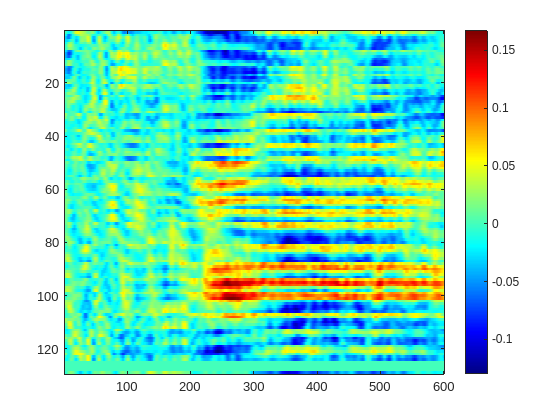

figure, imagesc(TimedGALdecoding.CorrelationMatrix.CorrelationR), colorbar, colormap jet

Again, we give the same format  to data in order to use EMEGS. This allow us to inspect the GAL results over time:

TopographyAcrossTime2emegs = TimedGALdecoding.Topography.TopographyAcrossTime;
TopographyAcrossTime2emegs(TopographyAcrossTime2emegs == 0) = chanceLevel;
SaveAvgFile('TopographyAcrossTime.at', TopographyAcrossTime2emegs)


Write averaged data with 129 sensors and 600 points to file:
TopographyAcrossTime.at


ans = 'TopographyAcrossTime.at'

to finally load the ".at" file on EMEGS similarly as done before:

% emegs2d

### GAL connectivity patterns

Generalization connectivity matrices indicate how diferent areas shows similar neural activity patterns during the trial. We can inspect the averaged GAL:

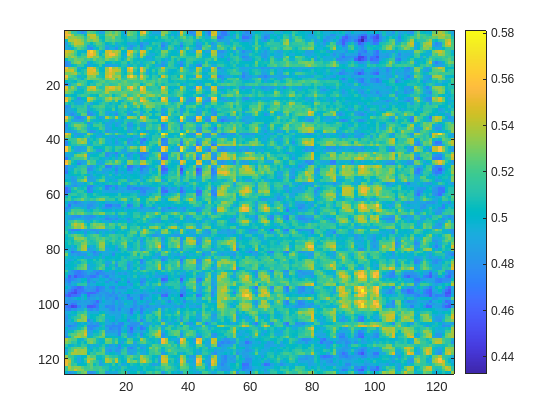

% For simplicity, extract generalization connectivity matrices to a
% short-named variable: GAL
GAL = TimedGALdecoding.GeneralizationMatrix.GeneralizationConnectivityMatrices;

figure,imagesc(squeeze(mean(GAL(:,channels,channels)))), colorbar

Next, we use the *n* generalization connectivity matrices to apply T-Students statistics contrasting whether the hit rate is avobe or below the chance-level (since we have only 2 condtions, 0.5).  Here, for example we will use an alpha of 0.05 corrected using Bonferroni method.

alpha_p_gal = 0.05 % This parameter can be modified

alpha_p_gal = 0.0500

Varying this threshold parameter we can observe more or less generalization connectivity patterns. Sometimes you need more resolution when signal-to-noise ratio is low, but for example in the case of steady-state responses a value of 0.01 is more than enough to find generalization connectivity patterns.

% We use bonferroni correction (alpha / number of comparisons)
bonferroniCorrection = alpha_p_gal/(length(channels)^2)

bonferroniCorrection = 3.2000e-06


% First we contrast those generalization connectivities above 0.5
[~,p] = ttest(GAL, chanceLevel, 'tail', 'right');
maskpos = squeeze(p < bonferroniCorrection);

% Then we contrast those generalization connectivities below 0.5
[~,p] = ttest(GAL, chanceLevel, 'tail', 'left');
maskneg = (squeeze(p < bonferroniCorrection)  )  * - 1;

% Finally, we obtain the masks indicating where in the matrix are direct
% generalization connectivities (+1) or inverse ones (-1)
maskposneg = maskpos + maskneg;

Now, we can plot the GAL in a circular graph showing the generalization connectivity pattern between areas of the topography:

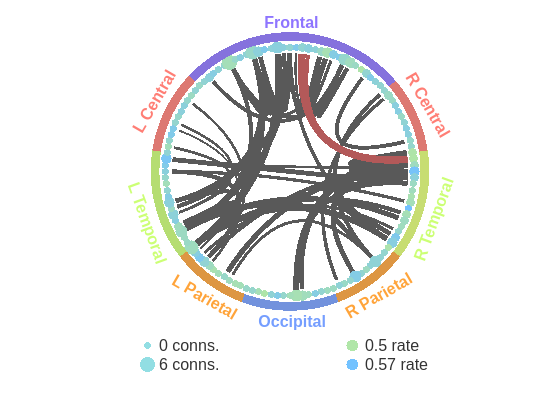

figure
circularTopography125static(squeeze(mean(GAL(:,channels,channels))), maskposneg(channels,channels), 1)

Finally, we can obtain the GAL connectivity patterns in time combining the information contained in the correlation matrix and the GAL matrices. Specifically, selecting those statistically significant GAL connections and the statistically significant time points. For the correlation matrix (i.e. temporal information) we will use a restrictive alpha value of 0.01, but no corrections are needed since we are not comparing between subjects. .

alpha_p_corr = 0.01 % This parameter can be modified

alpha_p_corr = 0.0100

pointTrigger = 100; % Here we indicate the task-related trigger
deltaT = 50; % Time lapse length between time-steps
sampleRate = 500; %Sample rate (Hz) of recording signal

Varying this threshold parameter we can observe a higher or lesser detail in the description of the temporal distribution of GAL generalization connectivity patterns

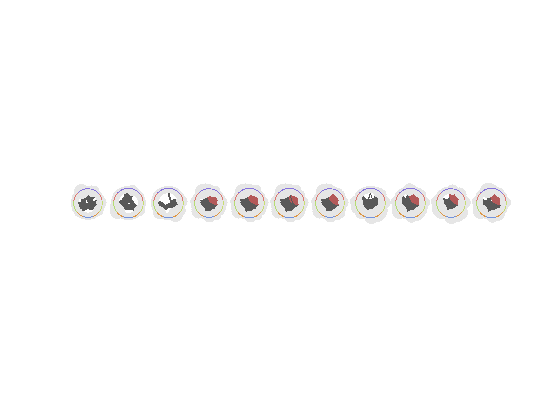

% First of all, we create the mask of statistically significant GAL links.
maskGAL = abs(maskposneg(channels,channels)); % cahnnel*channels

% Second, we create the mask of statistically significant correlation
% time points for each channel.
maskTime = TimedGALdecoding.CorrelationMatrix.CorrelationP(channels,:) < alpha_p_corr;

% look for those channels with any statistically significant GAL connection
indcs = find(sum(maskGAL)>=1);

% Now we mark those time/electrode points in the TimedGAL matrix.
[row, col] = find(maskGAL);
TimeGAL = zeros(125,125,601);
% looping over channels, we mark those indicated by time correlation matrix
for i = 1:length(row)
    TimeGAL(row(i),col(i), maskTime(row(i),:) == 1) = 1;
end

% and apply the value (positive/negative)
TimeGAL = TimeGAL.*maskposneg(channels,channels);

figure
% Finally we plot the circular graphs for each time step
count = 1;
% iterating over time every deltaT steps
for tm = pointTrigger - deltaT:deltaT:size(TimeGAL,3)-deltaT
    % we select the GALS for each time step
    tempStep = sum(TimeGAL(:,:,tm:tm+deltaT-1),3);
    % and plot them in each time exact subplot
    subplot(1,length(pointTrigger - deltaT:deltaT:size(TimeGAL,3)-deltaT),count)
    circularTopography125times(tempStep, deltaT, tm * 1000/sampleRate ,0)
    count = count + 1;
end

The last figure shows the GAL connectivity patterns along the trial time for the first deltaT before the trigger, and the rest of subplots post-stimulus presentation.